# Distributive imedance matching with Chebyshev and butterworth filter network

This document allows quick computation of cascated impedance matching network following the constrain of Fano bode criterian

## Parameters

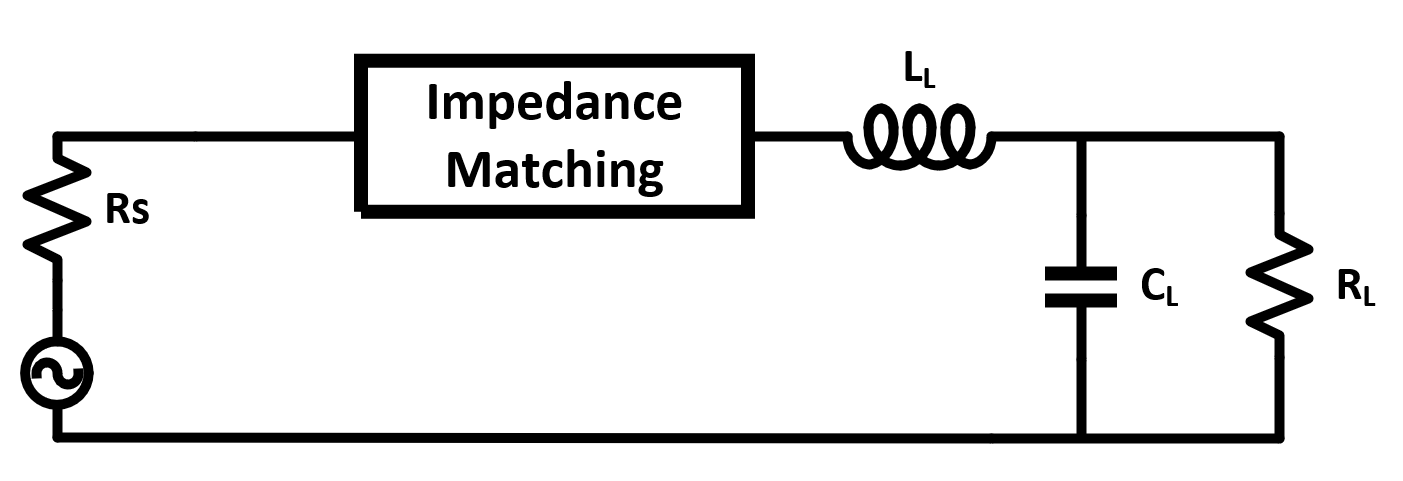

When using distributive matching network, we use Richards' transform where


$$\omega =\tan \left(\frac{\left(\omega \;\right)}{F_m *\textrm{div}}\right)\;\;\textrm{or}\;\;\;\;s=\tanh *\left(\frac{\omega \;}{F_m *\textrm{div}}\right)\;\;\textrm{div}\;\textrm{is}\;a\;\textrm{value}\;\textrm{of}\;8,\;16,32\ldotp \ldotp \ldotp \;,\textrm{note}:i*\tan \left(x\right)=\tanh \left(\textrm{ix}\right),\;i*\sin \left(x\right)=\sinh \left(\textrm{ix}\right),\;\cos \left(x\right)=\cosh \left(\textrm{ix}\right)$$


increase div reduces the numbers of harmonics in the system, The red curve is the circuit in F1 with div =16.

The blue curve is the cirucit in F2 with div=32. We see for the div=16 case the harmonic is 2 times that of the div=32:

The drawback is when div=32, we see extremely large and small characteristic impedances such as 518ohm and 11.25ohm which are difficult to implement

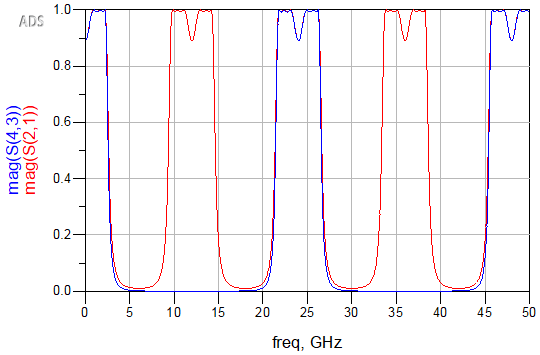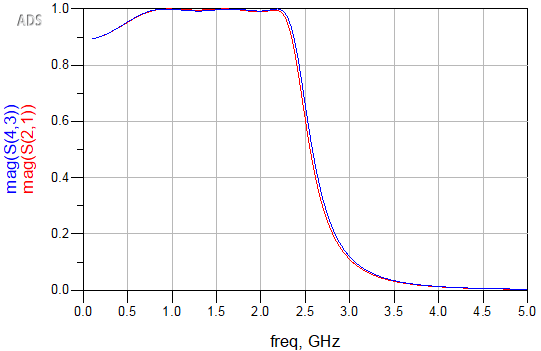

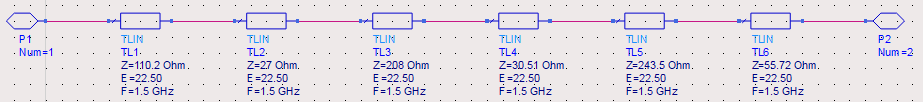F1 (Rs=50, Rl=133.3)

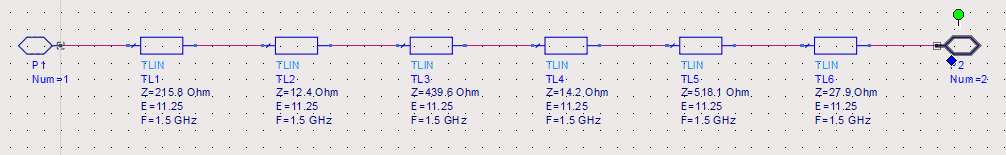F2 (Rs=50, Rl=133.3)

clear
format long
e=2.718281828459045;
% this is the only part that needs user input
Rl=133.3; % Load resistance
Cl=0.7095*10^-12;%12.48*10^-12; % Load capacitance
Ll=0.9675*10^-9;%0.1*10^-6; %Load inductance
Rs=50; %source resistance
% wstart=75*10^6; %start band
% wstop=125*10^6; %stop band
Fm=1.5*10^9; %passband center frequency: 
Bw=1; %0.5; %fractional bandwidth of the passband: (wb-wa)/wm should not be greater than 2
N=3; %order of the filter, large N gives a more ideal response, but need more component
lambdam= 3*10^8/Fm %the wavelength

lambdam =    0.200000000000000



%!!! change unit length of the transmission line here to /8, /16, /32,**%%
%    /64... the limitation is only that when the line length is too small,
%    the characteristic impedance value required might be impractival to
%    implement
div=16;
length=lambdam/div; %unit length of the transmission line

Ripple_reduction=0; 
% value from 0 to 1, 0 is the highest amount of ripple. 
% Only work for Chebyshev filter since butterworth have no ripple.
% increase this factor will rduced ripple, the trade off is less perfect matching. 

Cheby_or_but=1; %1 for chebyshev, 0 for butterworth

total_length=length*2*N %this is the total dimension of the design in meter, 

total_length =    0.075000000000000


%this value have no use in the code, it is only here as a reference for
%designers


## Component scaling and frequency transformation 

Because we used the method of frequency transformation, we defines:

W: $\Omega \;$the angular frequency for lowpass prototype (normalized)

w: $\omega \;$the angular frequency for the final high pass circuit (normalized)

Note: both W and w are normalized around 1, the final circuit is computer using Frequency transformatoin using Fm

% Fm=(wstop+wstart)/2 %passband center frequency: 
% Bw=(wstop-wstart)/Fm %fractional bandwidth of the passband: (wb-wa)/wm
if Bw > 2
    fprintf('bandwidth %f not synthesizable, modified Bw to 2',Bw)
    Bw=2
end

% First, normalize all components with respect to load resistance
Kn=1/Rl; % component scaling factor, resulting scaled component have the same frequency response
Rl1=Rl*Kn;
Ll1=Ll*Kn;
Cl1=Cl/Kn;

% Second, since we designed our filter around unity frequency, we need transfer frequency behaviour to unity
Kf=1/(Fm*2*pi); % frequency scaling factor Kf=targeted freq/original freq
Rl2=Rl1;
Ll2=Ll1/Kf;
Cl2=Cl1/Kf;

% frequency transfering variable: lowpass prototype to bandpass prototype
wm=1; %normalized passband centre angular frequency
wa=1-Bw/2; %normalized startband angular frequency
wb=1+Bw/2; %normalized stopband angular frequency
wo=sqrt((wa^2+wb^2)/2); %arithmetic mean wo
A=((wb^2-wa^2)/2); %is a constant that sets the bandwidth
syms W w% W for lowpass, w for bandpas
W=(w^2-wo^2)/A; %relationship between W & w for lumped 

% frequency tranfering variable: lowpass to band pass distributed network


Thm=2*pi*length/lambdam

Thm =    0.392699081698724


Tha=Thm*(1-Bw/2)

Tha =    0.196349540849362


Thb=Thm*(1+Bw/2)

Thb =    0.589048622548086


Tho=atan(sqrt( (tan(Thb)^2*(1+tan(Tha)^2)+tan(Tha)^2*(1+tan(Thb)^2)) /(2+tan(Tha)^2+tan(Thb)^2)))

Tho =    0.429442879364600


A2=(1+tan(Thb)^2)/(tan(Thb)^2-tan(Tho)^2)

A2 =    6.109731692418242


wo=tan(Tho)

wo =    0.457946894035274


W=A2*(w^2-wo^2)/(w^2+1)

$$W = \frac{\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}}{w^{2}+1}$$

## Integral restriction and termination ratios

The integral below is the Fano-Bode friterian. It represents the maximum theoretical integral restriction of the impedance matching network.

Our synthesized network should fall within this restriction 


$$\int_0^{\inf } \ln \left(\frac{1}{|\Gamma \;|}\right)d\omega =\frac{\pi \;}{R_l C_l \;}-\pi \;\sum_i \Gamma {\;}_{\textrm{ri}} \;\;\;\;\;\;\;\;\;\textrm{Eq1}\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}\;\textrm{configration}\;$$



$$\int_0^{\inf } \omega {\;}^2 \;\ln \left(\frac{1}{|\Gamma \;|}\right)d\omega =\frac{\pi \;}{C_l^3 \;}\left(\frac{C_l }{L_l }-\frac{1}{3}\right)+\frac{\pi }{3}\;\sum_i \Gamma {\;}_{\textrm{ri}}^3 \;\;\;\;\;\textrm{Eq2}\;\;\;\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}+\textrm{series}\;L\;\textrm{configration}\;$$


% When Ll=0, Eq2 does becomes infinity, so we use Eq1 when Ll=0

Fano=pi/(Rl2*Cl2)  %Ll=0 use eq1

Fano =    3.524489297095239



Fano2=pi/Cl2^3*(Cl2/Ll2-1/3) % Ll != 0, use eq 2

Fano2 =   56.324367621775693



flag=0

flag =      0


if Fano2<Fano %check if the second integral is satisified 
    Fano=Fano2;
    flag=1;
    fprintf('seonc fano criteria smaller than the first, choose the smaller one')
end


## Evaluate Chebyshev and Butterworth integral

In the section above, we found the maximum integral restriction. Now we evaluate the integral result of our filter polynomial to makes sure it is with in the Fano-Bode criterian.

We need to make sure that our design is just at the edge of the Fano-Bode criterian. This makes sure that we are taking the maximum bandwidth advantage. 

It also makes sure that the synthesized network have the same Cl and Ll, since we can't change those values. We need to evaluate the integrals below:


$$\int_0^{\inf } \ln \left(\frac{1}{|\Gamma \;|}\right)d\omega \;\;\;\;\;\;\;\;\textrm{Eq3}\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}\;\textrm{configration}\;$$



$$\int_0^{\inf } \omega {\;}^2 \;\ln \left(\frac{1}{|\Gamma \;|}\right)d\omega \;\;\;\;\textrm{Eq4}\;\;\;\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}+\textrm{series}\;L\;\textrm{configration}\;$$



$$\textrm{We}\;\textrm{know}\;\textrm{that}:\;|\Gamma |^2 =1-|S_{21} |^2 =\frac{\delta +{\epsilon {\;}^2 C}_n^2 }{1+\delta +\epsilon {\;}^2 C_n^2 }\;\to |\Gamma |=\sqrt{\frac{\delta +{\epsilon {\;}^2 C}_n^2 \left(\Omega \;\right)}{1+\delta +\epsilon {\;}^2 C_n^2 \left(\Omega \;\right)}\;}$$



$$\textrm{Butterworth}:C_n =\Omega \;{\;}^{2N} \to |\Gamma |=\sqrt{\frac{\delta +\epsilon {\;}^2 \Omega \;{\;}^{2N} }{1+\delta +\epsilon {\;}^2 \Omega \;{\;}^{2N} }\;}\;$$



$$\textrm{Chebyshev}:C_n \left(\Omega \;\right)=$$
 
$$\left\lbrace \begin{array}{ll}
\cosh^2 \left(N\;\cosh^{-1} \left(\Omega \;\right)\right) & \textrm{for}\;1\le \Omega \le \infty \;\\
\cos^2 \left(N\;\cos^{-1} \left(\Omega \;\right)\right) & \textrm{for}\;0\le \Omega \le 1
\end{array}\right.$$


           
$$\textrm{Or}:\;\;C_o \left(\Omega \;\right)=1\;$$


           
$$\;\;\;\;\;\;\;\;\;\;\;C_1 \left(\Omega \;\right)=\Omega \;\;$$


           
$$\;\;\;\;\;\;\;\;\;\;\;C_n \left(\Omega \;\right)=2\Omega C_{n-1} \left(\Omega \;\right)-C_{n-2} \left(\Omega \;\right)$$


Both forms are equivalent. We use the second form for integral analysis since arccosh() and arccos() are often undefined.


syms Cn d G ep% Cn, delta, G=1/gamma, epsilon^2

if Cheby_or_but ==0 %butterworth
    Cn=W^(N); 
else                %chebyshev
    if N==0
        Cn=1;
    elseif N==1
        Cn=W;
    else
        Cn1=W; %Cn-1 seeds for the recursion 
        Cn2=1; %Cn-2
        for i=1:N-1 %compute the correct polynomial based on the order N using recursion relation
            Cn=2*W*Cn1-Cn2
            Cn2=Cn1; %update seed value
            Cn1=Cn;  %update seed value
        end
    end
end

$$Cn = \frac{2\,{\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}^{2}}{{\left(w^{2}+1\right)}^{2}}-1$$

$$Cn = \frac{2\,\left(\frac{2\,{\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}^{2}}{{\left(w^{2}+1\right)}^{2}}-1\right)\,\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}{w^{2}+1}-\frac{\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}}{w^{2}+1}$$

## Termination ratio, delta and epsilon

standard synthesis process does not allow one to define termination ratio easily.

We choose the following equation


$$S_{21} \left(\frac{\left(0-\omega {\;}_0 \right)}{A}\right)=\frac{4r}{{\left(r+1\right)}^2 \;}\;\;$$


$\textrm{Thus}:\frac{1}{S_{21} \left(\frac{0-\omega {\;}_0 }{A}\right)}=1+\delta +\epsilon {\;}^2 C_n^2 \left(\frac{\left(0-\omega {\;}_0 \right)}{A}\;\right)$=$=\frac{{\left(r+1\right)}^2 }{4r\;}$


$$\begin{array}{l}
\delta \;\;\textrm{is}\;\textrm{obtained}\;\textrm{by}\;\textrm{evaluating}\;\textrm{the}\;\textrm{Fano}\;\textrm{integral}\;\textrm{of}\;\textrm{the}\;\textrm{generated}\;\textrm{function}\ldotp \textrm{For}\;\textrm{Commensurate}\;\textrm{line}\;\textrm{circuits},\textrm{we}\;\textrm{know}\;\textrm{the}\;\textrm{frequency}\;\textrm{response}\;\textrm{is}\;\textrm{periodic}\;\textrm{which}\;\textrm{seems}\;\textrm{to}\;\textrm{preclude}\;\textrm{the}\;\textrm{evaluation}\;\textrm{of}\;\\
\textrm{the}\;\textrm{fano}\;\textrm{integral}\ldotp \textrm{However},\textrm{because}\;\textrm{the}\;\textrm{load}\;\textrm{have}\;a\;\textrm{parallel}\;\textrm{capacitance},\textrm{this}\;\textrm{attenuates}\;\textrm{the}\;\textrm{harmonic}\;\textrm{passbands}\ldotp \textrm{So}\;\textrm{we}\;\textrm{can}\;\textrm{approximate}\;\textrm{the}\;\textrm{integral}\;\textrm{using}\;\textrm{the}\;\textrm{first}\;\textrm{harmonic}\;\textrm{passband}\;\textrm{only}\ldotp 
\end{array}$$


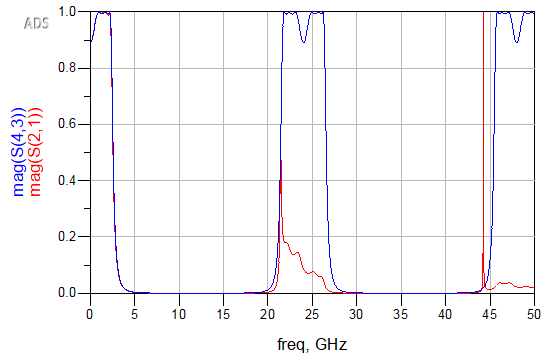

The blue curve is the frequency response of the circuit in F2 where we see the harmonic passband behaviour. The red curve is the frequency response of circuit in F1 where we see strong attenuation.

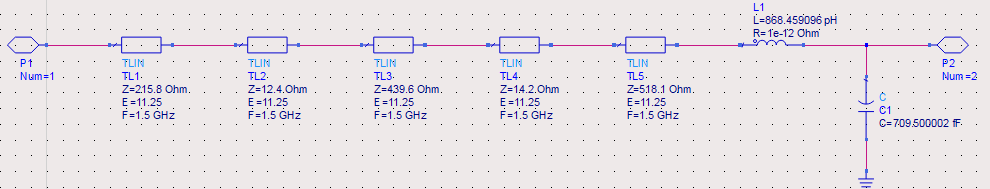F1 (Rs=50, Rl=133.3)

F2 (Rs=50, Rl=133.3)


r=Rl/Rs; % the termination ratio

% evaluate Cn((0-w0)/A)
w=0; %when frequency=0
Cn0=double(subs(Cn)); % this is Cn((0-w0)/A)
syms w s%return symbolyc variable w

%express epsilon in terms of delta
ep=(((r+1)^2)/(4*r)-1-d)/Cn0^2; %this is epsilon^2

%find ln(1/gamma)
G=log(sqrt((1+d+ep*Cn^2)/(d+ep*Cn^2)))

$$G = \begin{array}{l} \log\left(\sqrt{\frac{d-\sigma_{1}+1}{d-\sigma_{1}}}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}}{w^{2}+1}-\frac{2\,\left(\frac{2\,{\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}^{2}}{{\left(w^{2}+1\right)}^{2}}-1\right)\,\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}{w^{2}+1}\right)}^{2}\,\left(\frac{35184372088832\,d}{734940855969813}-\frac{912902945899}{73265132059296}\right) \end{array}$$


%intiial delta value,using newton's method to find the value%
attempt=4; %numbers of attempt in iteration
G1=subs(G)

$$G1 = \begin{array}{l} \log\left(\sqrt{\frac{d-\sigma_{1}+1}{d-\sigma_{1}}}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}}{w^{2}+1}-\frac{2\,\left(\frac{2\,{\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}^{2}}{{\left(w^{2}+1\right)}^{2}}-1\right)\,\left(\frac{3439473171663563\,w^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016}\right)}{w^{2}+1}\right)}^{2}\,\left(\frac{35184372088832\,d}{734940855969813}-\frac{912902945899}{73265132059296}\right) \end{array}$$

x=zeros(1,attempt);
y=zeros(1,attempt);

%d=linspace(0.00045,0.5,10);
w=tan(w*2*pi/div);%
GG=subs(G1)

$$GG = \begin{array}{l} \log\left(\sqrt{\frac{d-\sigma_{1}+1}{d-\sigma_{1}}}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\sigma_{2}}{{\tan\left(\frac{\pi \,w}{8}\right)}^{2}+1}-\frac{2\,\left(\frac{2\,{\sigma_{2}}^{2}}{{\left({\tan\left(\frac{\pi \,w}{8}\right)}^{2}+1\right)}^{2}}-1\right)\,\sigma_{2}}{{\tan\left(\frac{\pi \,w}{8}\right)}^{2}+1}\right)}^{2}\,\left(\frac{35184372088832\,d}{734940855969813}-\frac{912902945899}{73265132059296}\right)\\ \sigma_{2}=\frac{3439473171663563\,{\tan\left(\frac{\pi \,w}{8}\right)}^{2}}{562949953421312}-\frac{25987944068554369006566463659471}{20282409603651670423947251286016} \end{array}$$

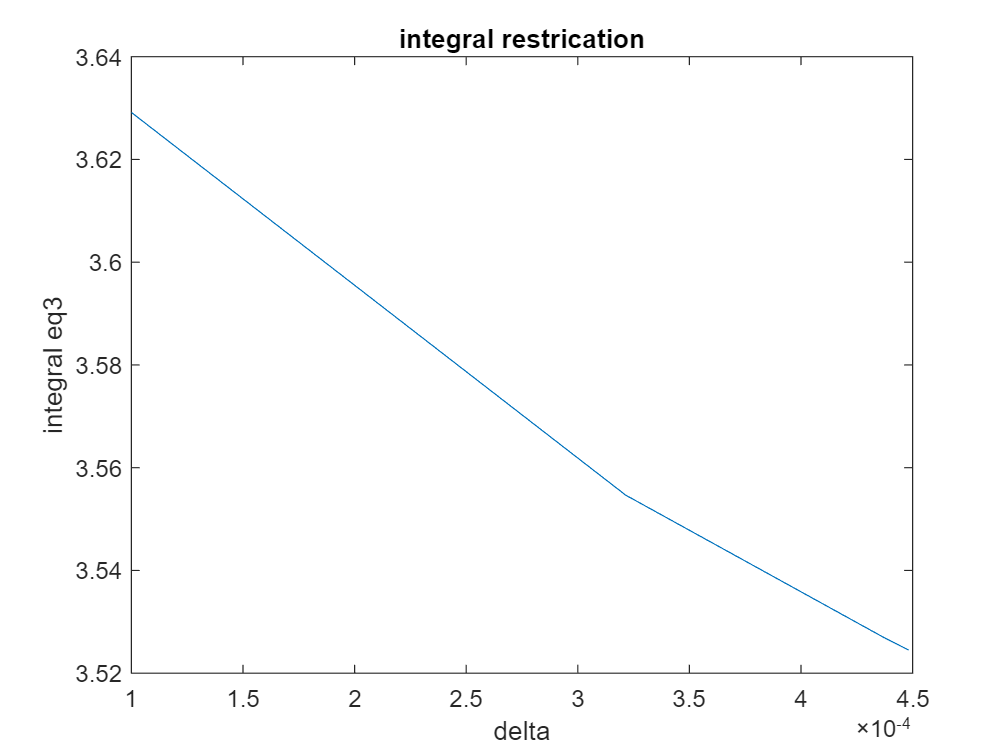

d=0.0001; 
if flag==0
    %integ=double(int(G1,w,0,inf)); analytical integral
    integ3=vpaintegral(GG,0,2.2); % numerical integral, it is much much faster than analytical integral
    a1=double(subs(integ3));
    a2=double(subs(integ3));
    if Fano<a1 % else we already satisfied the Fano-Bode criterian, break the loop
        for i=1:attempt
            x(i)=d; %store it for latter plotting 
            a1=double(subs(integ3));
            y(i)=a1;
            d=d*1.0001;
            a2=double(subs(integ3));
            Fp=(a2-a1)/(0.0001*x(i)); %find derivatice for newton's method 
            d=d+(Fano-a2)/Fp; %newton's method
        end
        
        %only plot when Fano<a1, otherwise there is no data to plot.
        plot(x,y,'-');
        xlabel('delta') 
        ylabel('integral eq3') 
        title('integral restrication')
    end
% else
%     G2=G1*w^2;
%     integ3=vpaintegral(G2,0,inf); % numerical integral, it is much much faster than analytical integral
%     a1=double(subs(integ3));
%     a2=double(subs(integ3));
%     if Fano<a1 % else we already satisfied the Fano-Bode criterian, break the loop
%     for i=1:attempt
%         x(i)=d; %store it for latter plotting 
%         a1=double(subs(integ3));
%         y(i)=a1;
%         d=d*1.0001;
%         a2=double(subs(integ3));
%         Fp=(a2-a1)/(0.0001*x(i)); %find derivatice for newton's method 
%         d=d+(Fano-a2)/Fp; %newton's method
%     end
%     
%     %only plot when Fano<a1, otherwise there is no data to plot.
%     plot(x,y,'-');
%     xlabel('delta') 
%     ylabel('integral eq3') 
%     title('integral restrication')
%     end

end


% integ3=vpaintegral(GG,0,2)
% y=double(subs(integ3))
% 
% plot(d,abs(y))

%d=0.00045 %user defined delta, common out this line if want automatic delta!!!!!!!
ep=subs(ep) % now we can find epsilon

$$ep = \frac{1597642823290239065}{128440223831567106048}$$

## Find poles

%find poles using numerical method
w=-1i*s;
Cn2=subs(Cn);
% Gam_num=d+ep*Cn2^2
% Gam_den=1+d+ep*Cn2^2
[Gam_num, Gam_den]=numden((d+ep*Cn2^2)/(1+d+ep*Cn2^2));

a=sym2poly(Gam_num);
b=sym2poly(Gam_den);
z=roots(a)

z =   -0.0066 + 0.6403i
  -0.0066 - 0.6403i
   0.0066 + 0.6403i
   0.0066 - 0.6403i
  -0.0136 + 0.4580i
  -0.0136 - 0.4580i
   0.0136 + 0.4580i
   0.0136 - 0.4580i
  -0.0098 + 0.2436i
  -0.0098 - 0.2436i


p=roots(b)

p =   -0.1211 + 0.7285i
  -0.1211 - 0.7285i
   0.1211 + 0.7285i
   0.1211 - 0.7285i
  -0.2275 + 0.4713i
  -0.2275 - 0.4713i
   0.2275 + 0.4713i
   0.2275 - 0.4713i
  -0.2044 + 0.1833i
  -0.2044 - 0.1833i



coeff=sqrt(a(1)/b(1)) %we can't just multiply the roots together

coeff =    0.999949703831234


%we have to care about coefficient

%frequency transform lowpass to bandpass configuration
pb=zeros(2,2*N);%poles for the bandpass prototype
zb=zeros(2,2*N); %zeros for the bandpass prototype

i1=1; i2=1; i3=1; i4=1;
for i=1:4*N
    if real(z(i))<0 %check for answer in the LHP
       zb(2,i1)=z(i);
       i1=i1+1;
    else 
       zb(1,i2)=z(i);
       i2=i2+1;
    end

    if real(p(i))<0 %check for answer in the LHP
       pb(2,i3)=p(i);
       i3=i3+1;
    else 
       pb(1,i4)=p(i);
       i4=i4+1;
    end
end

syms s x

num=expand(prod(s-zb(2,:)))*coeff;
den=expand(prod(s-pb(2,:)))

$$den = s^{6}+\frac{19920641748736949\,s^{5}}{18014398509481984}+\frac{837127750398801147673974545616605\,s^{4}}{649037107316853453566312041152512}+\frac{4366523759714104058079396285936268560514529008051\,s^{3}}{5846006549323611672814739330865132078623730171904}+\frac{36647198246370271329857326967683746427097699097884384403809991023\,s^{2}}{105312291668557186697918027683670432318895095400549111254310977536}+\frac{20101197595280719662247079312287984820825967596263075520937070861278513759499333\,s}{237142198758023568227473377297792835283496928595231875152809132048206089502588928}+\frac{96198430271531627102652016395971436809156693434286013790064317135147190746537118204750111451725}{8543948143683640329580086824678208458410818089426611079788166431288878903122562200091848347746304}$$

% den=1;num=1;
% for i=1:2*N
%     num=(s-zb(2,i))*num
%     den=(s-pb(2,i))*den
% end
Num=sym2poly(num);
Den=sym2poly(den);
Gamma=tf(Num,Den)

Gamma =
 
  s^6 + 0.06004 s^5 + 0.6805 s^4 + 0.0285 s^3 + 0.1232 s^2 + 0.002516 s + 0.005117
  --------------------------------------------------------------------------------
     s^6 + 1.106 s^5 + 1.29 s^4 + 0.7469 s^3 + 0.348 s^2 + 0.08476 s + 0.01126
 
Continuous-time transfer function.




index=linspace(0,Fm+1.5*Fm*Bw,150); %find 20 values
Gamma2=num/den; %same as Gamma, just in symbolic form
Gammat=Gamma2; % same as Gamma, used to plot tangent
s=tanh(1i.*index*2*pi/(Fm*div));%index would be frequency in Hz
Gamma3=subs(Gamma2); %same as Gamma, just in numerical form for 20 points
S21=1-double(abs(Gamma3)).^2; %this is s21*s21
plot(index,(S21),'LineWidth',1.6,'Color',[0 0.4470 0.7410])
axis("tight")
hold

Current plot held


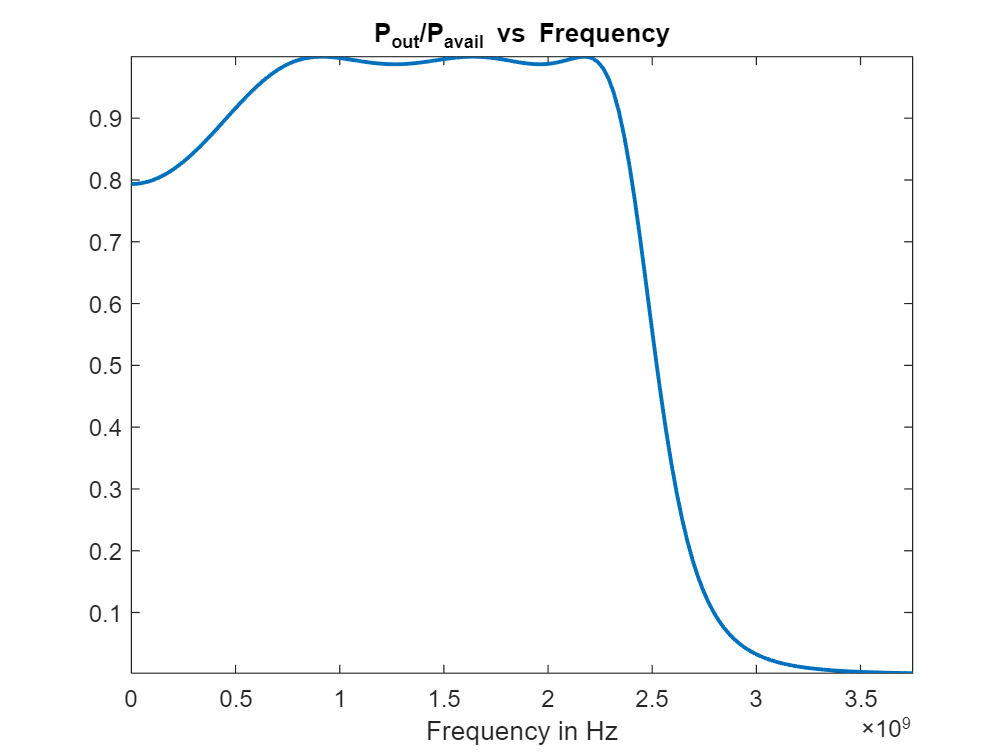


% %plot what is the theoretically allowed perfect filter
% D=2*pi/(Rl2*Cl2*Bw);
% F=D*(heaviside(x-wa)-heaviside(x-wb));
% S=1-e^(-F);
% %fplot(S,[0,2],'--','LineWidth',1.3,'Color',[0.8500 0.3250 0.0980])
% x=index;
% Brick=subs(S);
% plot(index*Fm,Brick,'--','LineWidth',1.3,'Color',[1 0 0])
% 
% legend('Wideband IM 1','Ideal brick-wall filter')
 xlabel('Frequency in Hz') 
% %ylabel('watts/Hz') 
 title('P_{out}/P_{avail} vs Frequency')

% % fplot(1/(1+ep*Cn^2),[0,2]) %use this to check if we have the right s11
% % poles computed, should give same graph 


## find impedamce

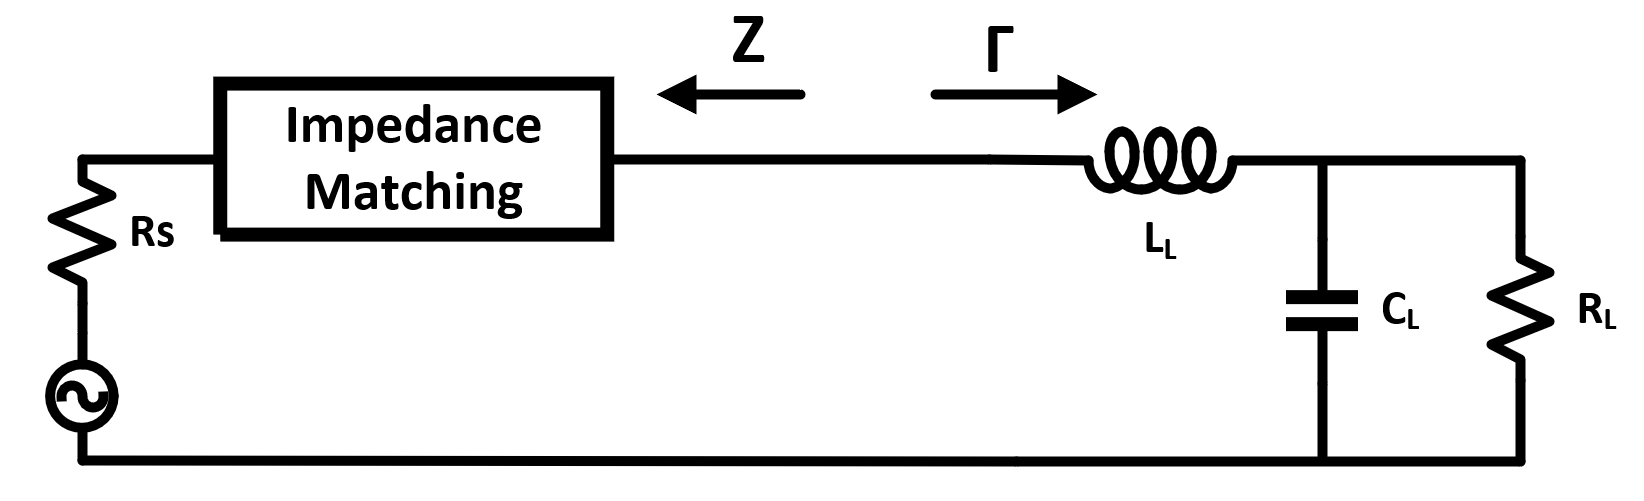


$$Z=\frac{\left(1-\Gamma \;\right)}{\left(1+\Gamma \right)}$$


num_rho_1_mapped = tf(Num,1);
den_rho_1_mapped = tf(Den,1);
Z = (den_rho_1_mapped - num_rho_1_mapped)/...
    (den_rho_1_mapped + num_rho_1_mapped)

Z =
 
  5.03e-05 s^6 + 1.046 s^5 + 0.6093 s^4 + 0.7184 s^3 + 0.2248 s^2 + 0.08225 s + 0.006143
  --------------------------------------------------------------------------------------
       2 s^6 + 1.166 s^5 + 1.97 s^4 + 0.7754 s^3 + 0.4712 s^2 + 0.08728 s + 0.01638
 
Continuous-time transfer function.




syms s
[num,den] = tfdata(Z);
Z = poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s);

%Z=(1-Gamma2)/(1+Gamma2);

## Richards' transform

we use richards' method of commensurate line to peal off each of the terms in the polynomial


$$Z^{\prime } =\frac{\left(Z-SZ_1 \right)}{\left(1-\frac{Z}{Z_1 }S\right)}\;\;\textrm{where}\;\;Z_1 =\left(\textrm{the}\;\textrm{value}\;\textrm{of}\;Z\;\textrm{at}\;S=1\right)$$


lineimpedance=zeros(N*2+2,1);
i=2

i =      2


while(1)
    [c1, c2] = numden(Z);
    p1=double(coeffs(c1,'All'));
    p2=double(coeffs(c2,'All'));
    
    cc=p1(1)/p2(1);
    
    P1=roots(p1);
    P2=roots(p2);

    [c11, c22] = numden(Z); %split into polynomial
    degreenum=polynomialDegree(c11);
    degreeden=polynomialDegree(c22);
    if(degreenum==0 || degreeden ==0)
        break
    end
    lineimpedance(i)=double(subs(Z,1));
    Z=transform(Z,1);
    i=i+1;

end

lineimpedance(2*N+2)=double(Z); %the final resistor value
lineimpedance(1)=Rl % initial resistor value

lineimpedance = 	1.0e+00 *

  133.3000
    0.4142
    1.8098
    0.2268
    1.5464
    0.2011
    0.8243
    0.3751


lineimpedance=lineimpedance*Rl %denormalize

lineimpedance = 	1.0e+04 *

    1.7769
    0.0055
    0.0241
    0.0030
    0.0206
    0.0027
    0.0110
    0.0050


%interestingly, we don't have to do frequency transformation, this is
%because the commensurate line length are set to lambda/16, choose lambda
%corresponds to the desired centre frequency will be sufficient

function Zp = transform(Z,l)
    syms s
    z=double(subs(Z,l));
    Z1=(Z-s*z)/(l-s * Z/z);
    Zp=removepoles(Z1,0.0001);
end


%Some times a rational fucntion have same root on the top and bottom,
%however, because the rounding errors in actual calcualtion, matlab is not
%able to cancel those roots. This function cancels out roots that are
%different by a defined error range. error=0.0001 is a good approximation
function Zp = removepoles(Z,error)
    syms s
    [c1, c2] = numden(Z);
    p1=double(coeffs(c1,'All'));
    p2=double(coeffs(c2,'All'));
    
    cc=p1(1)/p2(1);
    
    P1=roots(p1);
    P2=roots(p2);
    
    i=1;
    i2=1;

    while i<= numel(P1)
        while i2 <=numel(P2)
            difference=abs(P1(i)-P2(i2));
            if(difference<error) %same root top and bottom, reject this root
                P1(i)=[];
                P2(i2)=[];
                i=i-1;
                break %no need to proceed further
            else
                i2=i2+1;
            end
        end
        i2=1; %reinitialize i2
        i=i+1;
    end
    
    p11=expand(prod(s-P1));
    p22=expand(prod(s-P2));
    Zp=p11/p22*cc;
end